## Car Crash Predictions Using Regression Model Learning

by Derek Xu, Anthony O'Neil, David Xiang

#### Article Citation and Synopsis

Automobile crashes are one of the top causes of death and injury in the United States today. *Motor Vehicle Collisions - Crashes* describes one way in which New York City has moved to help eliminate this reoccurring issue. The article explains the way in which they utilized NYPD police reports on crashes to help develop a dataset that describes where, when, and how automobile and automobile related crashes occur within New York City. These reports (the MV104-AN report) stemmed from two programs, the CompStat program and the TrafficStat program. The CompStat program was designed to help the police “reduce crime and achieve other police department goals” utilizing accurate and timely information, rapid deployment of resources, effective methods, and thorough follow-up. TrafficStat is a subset of this program to help reduce and effectively understand the causes and effects of automobile crashes, specifically in New York City. With this process, the NYPD have gotten an immense number of data points on car crashes over $1000 within the city along with detailed data fields such as Date-Time, Borough, and Injury/Death number. 

The main issue with this article and the data set that it creates is the fact that the motor vehicle collisions model only extracts data from police reports within New York City, meaning that it might be representative of crashes in other major cities, but more likely to not represent crashes within suburbs or rural areas. Another form of bias is the fact that reports are only made on crashes above $1000, meaning that the motor vehicle crashes dataset also only has data on those incidents. This means that many smaller events, such as parking collisions or slight cosmetic damage crashes will note be reported and not be present. Lastly, a major point of bias with this article and its methodology is that it utilizes police reports to contribute to the dataset. Crashes could be happening at much higher rates and in many different areas but are not reported, meaning that the dataset could be misrepresenting the actual amount of crash cases. Overall, this dataset has a multitude of detailed data points and the article well describes the methodology in obtaining these statistics along with ways that they have improved the system using technology such as digital entry and CCTV.

**Dataset and Sources**

Injurystats - [https://injuryfacts.nsc.org/motor-vehicle/overview/introduction/](https://injuryfacts.nsc.org/motor-vehicle/overview/introduction/)

Dataset and Article: [https://catalog.data.gov/dataset/motor-vehicle-collisions-crashes](https://catalog.data.gov/dataset/motor-vehicle-collisions-crashes)

Compstat Paper: [https://www.ojp.gov/ncjrs/virtual-library/abstracts/compstat-its-origins-evolution-and-future-law-enforcement-agencies](https://www.ojp.gov/ncjrs/virtual-library/abstracts/compstat-its-origins-evolution-and-future-law-enforcement-agencies)

#### Background and High-Level Explaination of Problem

According to Injuryfacts.nsc.org, over motor vehicle accidents are one of the top causes of death and injury within the United States at 21%, just under the number one spot for poisoning. These accidents are caused by a multitude of factors that can all come together to ultimately create a devastating incident. Many of these crashes can become fatal especially when it becomes car to pedestrian incidents. For our project, we have decided to analyze a government dataset on vehicular collisions in New York City in an attempt to find out what one major factor of these various variables contributes to automobile crashes, the time. The *Motor Vehicle Collisions - Crashes * dataset includes a plethora of variables, including the weather (and more specifically, which season of the year it is), recklessness, road rage, time, and more. 

 In our case, we want to analyze and accurately predict the fatality of crashes based on the time since the time contributes to many factors such as the number of cars on the road, what type of drivers there are (workers, drunk drivers, etc.) and visibility.  We prioritize creating a regression model that will take the time of day as the input and give us the cumulation of the number of deaths and injuries that occur within crashes in New York City. In creating a model that accurately describes the number of deaths and injuries within certain time frames, we can use this info to predict for other cities as well as other areas, what type of civil improvements that are needed. For example, if the most of the crashes occur mid-day during rush hour, then it is clear that reducing the number of cars on the road, through means of public transportation as a possible solution, would be needed to reduce automobile fatality. On the other hand, if crashes occur mostly at night, there would be other factors to look into such as decreasing the number of drunk drivers or improving visibility for drivers through means of more street lights. Overall, in solving this problem where we find the likelihood of automobile related crashes based on the time, we hope to create an understandable answer that can help drivers and pedestrians find safer times to travel and avoid incidents. More importantly, we hope that our machine learning model will help civil engineers and other city planners to create more effective infrastructure to decrease the total number of automobile related incidents as a whole.

#### Solution Process and Inferences

To find the answer to our problem, we first shrunk our sample size. We took one random datapoint in every 50 of the original dataset, to avoid any data bias. We then removed points missing information that may be vital: Borough, Street, and Cause of Collision. Once the data was scrubbed, we attempted to use the Classification and Regression Learners to produce valuable data; we realized that the Regression Learner would be more useful than the Classification Learner, so we stuck with that. However, our first few attempts at datamatching proved unsuccessful. The combinations of Injuries/Kills and Boroughs and Injuries/Kills and Streets didn't work, as we needed numerical values to do a true comparison. While giving the Boroughs a numerical ID would work, the result would be similar to a bar graph. Finally, we used Time against Injuries/Kills, which proved both successful and useful, so we stuck with that.

## Importing the Data

tic
crashdata = table2struct(webread("https://data.cityofnewyork.us/api/views/h9gi-nx95/rows.csv?accessType=DOWNLOAD"));

## Scrubbing the Data

Determining the size of the dataset, as well as how many points are actually going to be analyzed.

[r,~] = size(crashdata);
fprintf("There are a total of %d datapoints\n",r)

There are a total of 1951515 datapoints


fprintf("Since we don't want nearly that many datapoints, we'll use one random point in ever 50 in the set\n")

Since we don't want nearly that many datapoints, we'll use one random point in ever 50 in the set


format long g
maxval = floor(r/50);

%this loop eliminates all datapoints outside 
for i = r:-1:(maxval*50)+1
    crashdata(i) = [];
end

%under this, the last row of cleandata is given the last row of crashdata.
%This is temporary, and used to allow preallocation.
clear cleandata
cleandata(maxval) = crashdata(maxval*50);
for i = 1:maxval
    rannum = randi([1,50]);
    cleandata(i) = crashdata(rannum + ((i-1)*50));
end

cleandata = cleandata'

cleandata = 39030×1 struct array with fields:
    CRASHDATE
    CRASHTIME
    BOROUGH
    ZIPCODE
    LATITUDE
    LONGITUDE
    LOCATION
    ONSTREETNAME
    CROSSSTREETNAME
    OFFSTREETNAME
    NUMBEROFPERSONSINJURED
    NUMBEROFPERSONSKILLED
    NUMBEROFPEDESTRIANSINJURED
    NUMBEROFPEDESTRIANSKILLED
    NUMBEROFCYCLISTINJURED
    NUMBEROFCYCLISTKILLED
    NUMBEROFMOTORISTINJURED
    NUMBEROFMOTORISTKILLED
    CONTRIBUTINGFACTORVEHICLE1
    CONTRIBUTINGFACTORVEHICLE2
    CONTRIBUTINGFACTORVEHICLE3
    CONTRIBUTINGFACTORVEHICLE4
    CONTRIBUTINGFACTORVEHICLE5
    COLLISION_ID
    VEHICLETYPECODE1
    VEHICLETYPECODE2
    VEHICLETYPECODE3
    VEHICLETYPECODE4
    VEHICLETYPECODE5


[rclean,~] = size(cleandata);
fprintf("The size of the scrubbed data is now %d\n",rclean)

The size of the scrubbed data is now 39030


Now that the datapool has been decreased to a workable size, we're going to elminate datapoints that won't help us. This includes ones with no specified Borough, no specified causation factor (for at least 1 vehicle), and no specified streetname.

NB: Each step in the following scrubbing is run 5 times. MATLAB tends to miss a value occasionally, so repeating the process solves this issue.

%this loop eliminates values with no Borough
for i = 1:5
    idex = 1;
    while idex <= rclean
        if isempty(cleandata(idex).BOROUGH) || isnan(cleandata(idex).ZIPCODE)
                cleandata(idex) = [];
        end
        idex = idex + 1;
        [rclean,~] = size(cleandata);
    end
end

cleandata

cleandata = 26896×1 struct array with fields:
    CRASHDATE
    CRASHTIME
    BOROUGH
    ZIPCODE
    LATITUDE
    LONGITUDE
    LOCATION
    ONSTREETNAME
    CROSSSTREETNAME
    OFFSTREETNAME
    NUMBEROFPERSONSINJURED
    NUMBEROFPERSONSKILLED
    NUMBEROFPEDESTRIANSINJURED
    NUMBEROFPEDESTRIANSKILLED
    NUMBEROFCYCLISTINJURED
    NUMBEROFCYCLISTKILLED
    NUMBEROFMOTORISTINJURED
    NUMBEROFMOTORISTKILLED
    CONTRIBUTINGFACTORVEHICLE1
    CONTRIBUTINGFACTORVEHICLE2
    CONTRIBUTINGFACTORVEHICLE3
    CONTRIBUTINGFACTORVEHICLE4
    CONTRIBUTINGFACTORVEHICLE5
    COLLISION_ID
    VEHICLETYPECODE1
    VEHICLETYPECODE2
    VEHICLETYPECODE3
    VEHICLETYPECODE4
    VEHICLETYPECODE5


%this loop elmimnates values with no streetname
for i = 1:5
    idex = 1;
    while idex <= rclean
        if isempty(cleandata(idex).ONSTREETNAME)
                cleandata(idex) = [];
        end
        idex = idex + 1;
        [rclean,~] = size(cleandata);
    end
end
cleandata

cleandata = 21295×1 struct array with fields:
    CRASHDATE
    CRASHTIME
    BOROUGH
    ZIPCODE
    LATITUDE
    LONGITUDE
    LOCATION
    ONSTREETNAME
    CROSSSTREETNAME
    OFFSTREETNAME
    NUMBEROFPERSONSINJURED
    NUMBEROFPERSONSKILLED
    NUMBEROFPEDESTRIANSINJURED
    NUMBEROFPEDESTRIANSKILLED
    NUMBEROFCYCLISTINJURED
    NUMBEROFCYCLISTKILLED
    NUMBEROFMOTORISTINJURED
    NUMBEROFMOTORISTKILLED
    CONTRIBUTINGFACTORVEHICLE1
    CONTRIBUTINGFACTORVEHICLE2
    CONTRIBUTINGFACTORVEHICLE3
    CONTRIBUTINGFACTORVEHICLE4
    CONTRIBUTINGFACTORVEHICLE5
    COLLISION_ID
    VEHICLETYPECODE1
    VEHICLETYPECODE2
    VEHICLETYPECODE3
    VEHICLETYPECODE4
    VEHICLETYPECODE5


%finally, this loop eliminates datapoints with unspecified causes
for i = 1:5
    idex = 1;
    while idex <= rclean
        if  strcmp(cleandata(idex).CONTRIBUTINGFACTORVEHICLE1,'Unspecified') || isempty(cleandata(idex).CONTRIBUTINGFACTORVEHICLE1)
                cleandata(idex) = [];
        end
        idex = idex + 1;
        [rclean,~] = size(cleandata);
    end
end
cleandata

cleandata = 12743×1 struct array with fields:
    CRASHDATE
    CRASHTIME
    BOROUGH
    ZIPCODE
    LATITUDE
    LONGITUDE
    LOCATION
    ONSTREETNAME
    CROSSSTREETNAME
    OFFSTREETNAME
    NUMBEROFPERSONSINJURED
    NUMBEROFPERSONSKILLED
    NUMBEROFPEDESTRIANSINJURED
    NUMBEROFPEDESTRIANSKILLED
    NUMBEROFCYCLISTINJURED
    NUMBEROFCYCLISTKILLED
    NUMBEROFMOTORISTINJURED
    NUMBEROFMOTORISTKILLED
    CONTRIBUTINGFACTORVEHICLE1
    CONTRIBUTINGFACTORVEHICLE2
    CONTRIBUTINGFACTORVEHICLE3
    CONTRIBUTINGFACTORVEHICLE4
    CONTRIBUTINGFACTORVEHICLE5
    COLLISION_ID
    VEHICLETYPECODE1
    VEHICLETYPECODE2
    VEHICLETYPECODE3
    VEHICLETYPECODE4
    VEHICLETYPECODE5


fprintf("The final size of the data is %d datapoints\n",rclean)

The final size of the data is 12743 datapoints


toc

Elapsed time is 486.045942 seconds.


save cleandata.mat cleandata

Finally, the data can be analyzed in the ML Toolbox

## Vectorizing Code

In this section, three vectors are created: one is the total amount of people killed per crash, another is the total amount of those injured, and the last is the time of each of the crashes. These will be used in the machine learning toolbox.

load cleandata.mat
[rclean, cclean] = size(cleandata);
kills = zeros(rclean,1);
for i = 1:rclean
    kills(i) = cleandata(i).NUMBEROFPERSONSKILLED + cleandata(i).NUMBEROFPEDESTRIANSKILLED + cleandata(i).NUMBEROFCYCLISTKILLED + cleandata(i).NUMBEROFMOTORISTKILLED;
end
kills

kills =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


injurs = zeros(rclean,1);
for i = 1:rclean
    injurs(i) = cleandata(i).NUMBEROFPERSONSINJURED + cleandata(i).NUMBEROFPEDESTRIANSINJURED + cleandata(i).NUMBEROFCYCLISTINJURED + cleandata(i).NUMBEROFMOTORISTINJURED;
end
injurs

injurs =      2
     2
     2
     0
     6
     0
     6
     0
     0
     0


time = zeros(rclean,1);
for i = 1:rclean
    temp = cleandata(i).CRASHTIME;
    time(i) = str2double(erase(temp, ':'));
end
time

time =          102
        1755
         840
        2221
           0
         315
        1030
        1700
        1138
        1730


%learnerinfo = table(injurs,kills,boroughs)
save times.mat time
save injuries.mat injurs
save kills.mat kills

## **Using Kill and Injurs Data**

Here, the injury and kills data are summed up.

suminj = zeros(1,48);
lbt = 0;
hbt = 50;
for i = 1:48
    lbt = 0 + 50 * (i-1);
    hbt = 50 + 50 * (i-1);
    for j = 1:length(cleandata)
        if (str2double(erase(cleandata(j).CRASHTIME,':')))  >=lbt-20 && (str2double(erase(cleandata(j).CRASHTIME,':'))  < hbt-20 )
        suminj(i) = suminj(i) + cleandata(j).NUMBEROFPERSONSINJURED + cleandata(j).NUMBEROFPERSONSKILLED + cleandata(j).NUMBEROFPEDESTRIANSINJURED + cleandata(j).NUMBEROFPEDESTRIANSKILLED + cleandata(j).NUMBEROFMOTORISTINJURED;
        end
    end
end

suminj = suminj';

%% This function depends on which time interval the crash happen, it adds the injuries and deaths into the body counts in its interval

## **Using Time Data**

*Divide the whole day into 24 intervals.*

lb = 0;
hb = 50;
num = 1;
tinterval = zeros(1,length(time));
while hb <= 2400
    for i = 1:length(time)
        
        if (time(i)>= lb-20 && time(i)<hb-20)
            tinterval(i) = num;
        end
    end
    num = num+1;
    lb = lb + 50;
    hb = hb + 50;
end
tinterval = tinterval';
%% this catagorize the crashe times into 48 different intervals 

Check the count of each time interval

tfreq = zeros(1,48);
while num >= 1
    for i = 1: length(time)
        if (tinterval(i) == num )
            tfreq(num) = tfreq(num) + 1;
        end
    end
    num = num -1;
end
tfreq = tfreq';

%% this count how often does crashes happens in each time intervals

Creating the timevector to graph:

timevec = strings([48,1]);
hourvec = zeros(1,48);
minvec = zeros(1,48);
sub = 0;
for i = 1:2:48
    hourvec(i) = sub;
    hourvec(i+1) = sub;
    sub = sub + 1 ;
end
for i = 1:2:48
    minvec(i) = 0;
    minvec(i+1) = 30;
end
strhour = string(hourvec);
strmin = string(minvec);
for i = 1:48 
    timevec(i) = strcat(strhour(i), "." , strmin(i));
end

timevec = str2double(timevec); %#ok<NASGU> 

%% this creats a time interval vector for machine learning

## Creating Regression Model and Validating

To create the model, we use the time as the input and the cumulation of deaths + injuries as the output. The model will then allow us to predict future times and their respective fatality rates for one day.

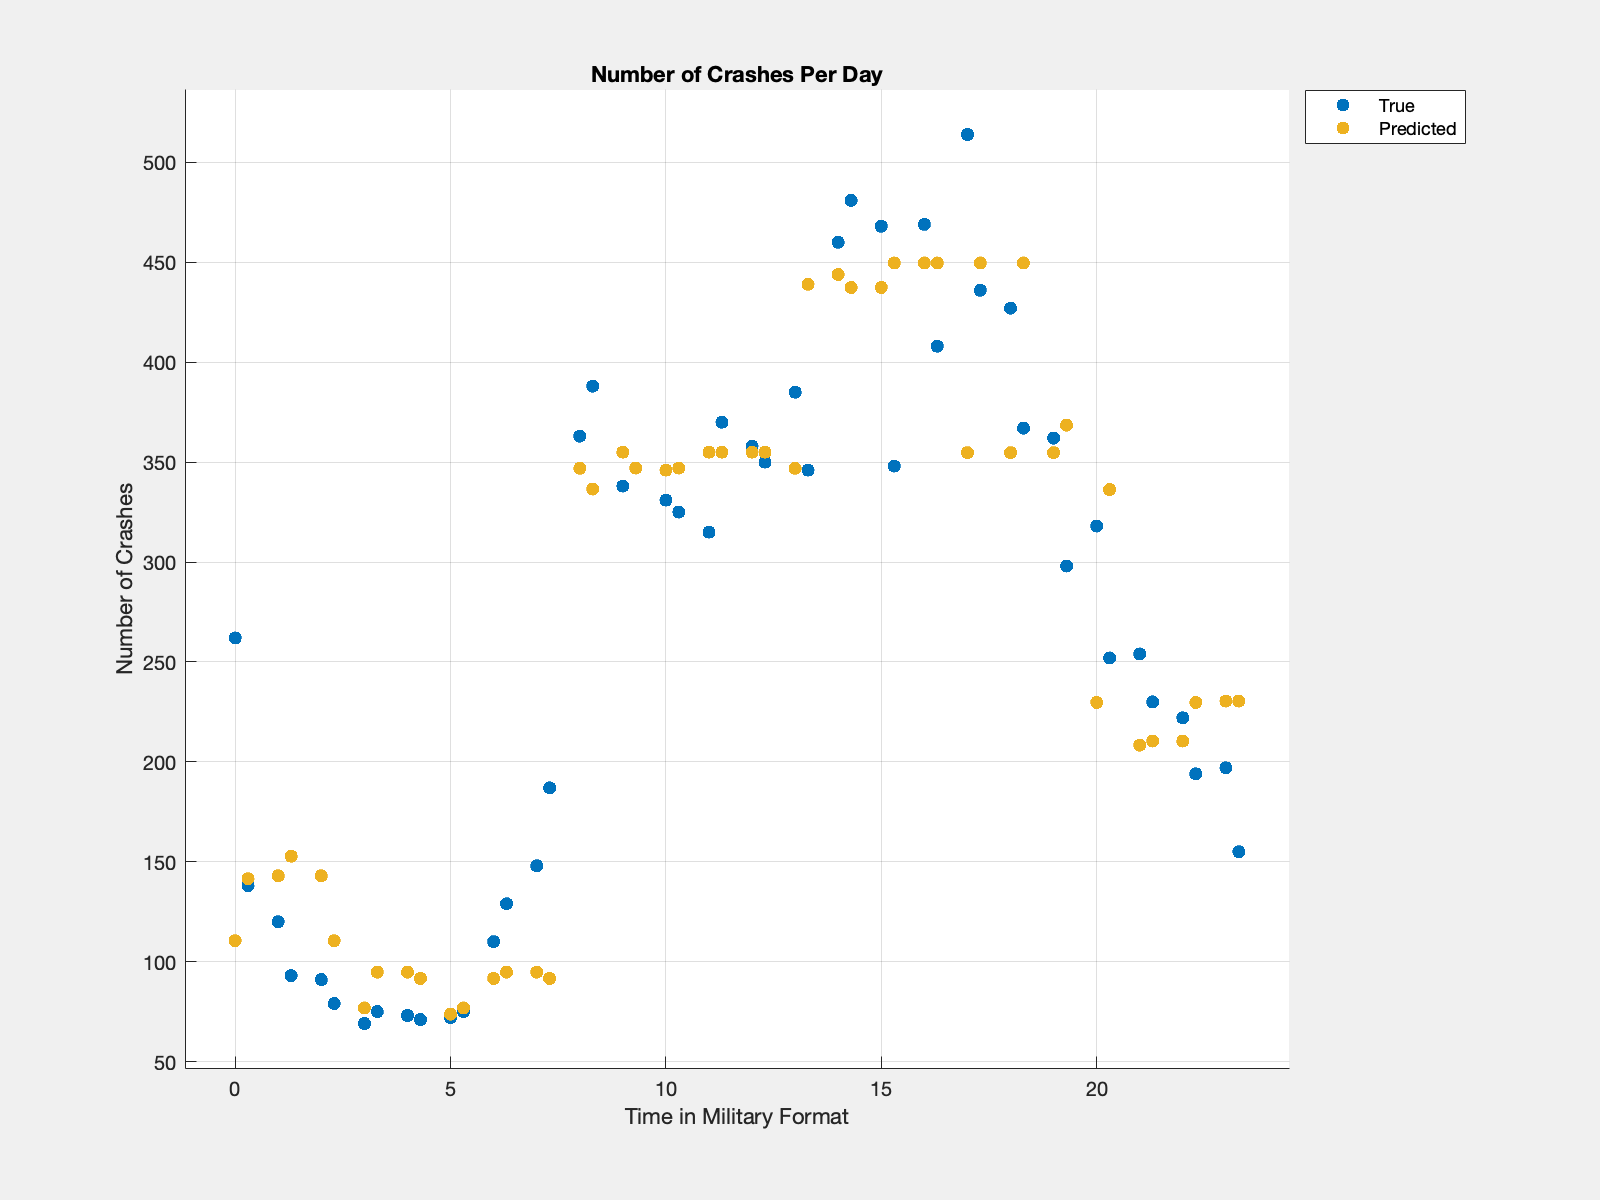

% loading the predicted and true graph to show accuracy of model for
% injuries+deaths
% these two next figures help validate the accuracy of the model
load injuryModel.mat
injuryFig = openfig('modelInjuriesPlot.fig');

figure(injuryFig)
xlabel('Time in Military Format')
ylabel('Sum of Injuries and Deaths')
title('Injury and Death Per Day Regression Model Results')
load frequencyModel.mat
frequencyFig = openfig('modelFrequencyPlot.fig');
% doing the same with frequencies
figure(frequencyFig)
xlabel('Time in Military Format')
ylabel('Number of Crashes')
title('Number of Crashes Per Day')

Next section will help show a possible use case where we input random times into the model to give us results.

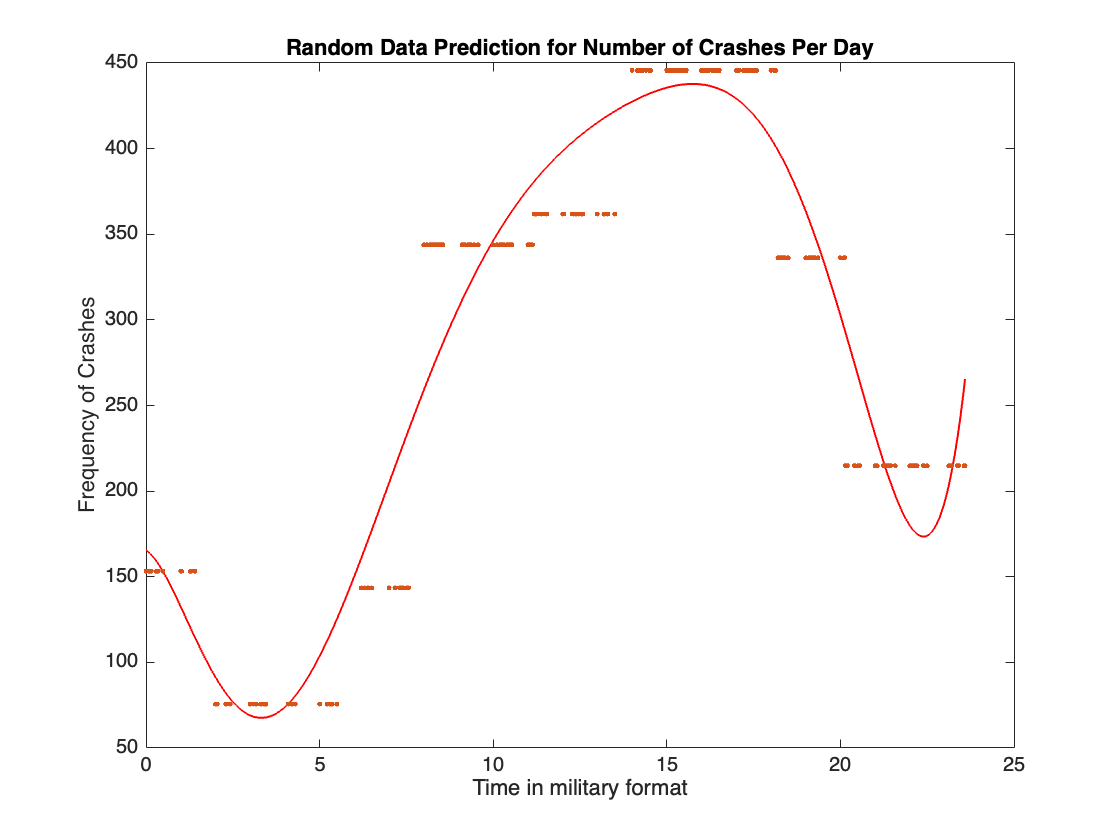

%creating a table of random data points to feed into model to show
% numerical results
load injuryModel.mat

% get random indices for the time
indices = randi([1, length(cleandata)], 300, 1);
timevec = zeros(300,1);
for i = 1:length(indices)
    temp = cleandata(i).CRASHTIME;
    timevec(i) = str2double(strrep(temp,':','.'));
end

% get predicted values
injuryTestOutput = injuryModel.predictFcn(timevec);

% polyfit
coefficients = polyfit(timevec, injuryTestOutput, 7);
xFit = linspace(min(timevec), max(timevec), 1000);
yFit = polyval(coefficients , xFit);
plot(xFit, yFit, 'r-', 'LineWidth', 1); % Plot fitted line.
hold on;

% plotting
plot(timevec, injuryTestOutput, '.')
xlabel('Time in military format')
ylabel('Sum of Deaths+Injuries')
title('Random Data Prediction for Injury/Deaths Per Day')
% same process for the frequency of crashes
figure
load frequencyModel.mat
frequencyTestOutput = frequencyModel.predictFcn(timevec);


% polyfit
coefficients = polyfit(timevec, frequencyTestOutput, 7);
xFit = linspace(min(timevec), max(timevec), 1000);
yFit = polyval(coefficients , xFit);
plot(xFit, yFit, 'r-', 'LineWidth', 1); % Plot fitted line.
hold on;

% plotting
plot(timevec, frequencyTestOutput, '.')
xlabel('Time in military format')
ylabel('Frequency of Crashes')
title('Random Data Prediction for Number of Crashes Per Day')
hold off

#### Conclusion

By referencing the graph, it can be inferred that the most dangerous time to drive in New York City is between 4pm and 7pm; considering that this is the usual time employees commute home, this lines up with normal logic. Furthermore, we also see that there is a decrease but still a significant amount of crashes during late night hours from 10pm to 1am. This could be also due to other factors such as drunk driving or poor visibility. When comparing the frequency of crashes to the number of injuries+deaths, we can also find that there are commonly more crashes than there are injuries+deaths. This is ratio is significantly higher especially higher during rush hours where a peak of 450 crashes have just about 250 injuries and deaths. This signifies that most of the crashes that happen within cities are small but prevalent. This could mean that there are issues with city planning in areas such as parking lots or other slower-paced areas, leading to more incidents without injury. Overall, our model gives good estimates on the trends of car crashes throughout the day and gives good insight onto what problems might lead to these issues.